# Fault Detection and Diagnostics Algorithm Design

This script walks through the data pre-processing and machine learning tasks required to design a fault detection algorithm. The machine learning technique can also be designed to perform fault diagnostics where the specific fault is determined from a single measurement.

This script requires outputs from the [Training Data Runs](matlab: edit sm_pump_triplex_sweep_training_data_runs.m) function which performs a Design of Experiments sweep of faults on the [Triplex Pump](matlab: sm_pump_triplex) model.

## Load Fault Time Series Data

Load data from multiple nominal and failure scenario simulations.

load('sm_pump_triplex_DOEdata.mat');

## Identify Tests with Faults

Remove nominal simulations to focus only on fault scenarios. Determine number of faults simulated from the unique tags in the simulated data and also count how many simulations of each unique fault were conducted.

[~,tFault,pFault,faultList] = sortFaultTests(test_Results);
faultNameList = unique(faultList);
numFaults = numel(faultNameList);
numSimsPerFault = length(find(strcmp(faultList,faultNameList{1})));

## Review Fault Progression in Time Domain

Raw senor data is plotted in the time domain. We can compare the nominal behavior of a triplex pump with behavior of the pump as elements within the pump degrade. The cyclical nature of the time domain signal provides unique signatures for each fault and fault combination.

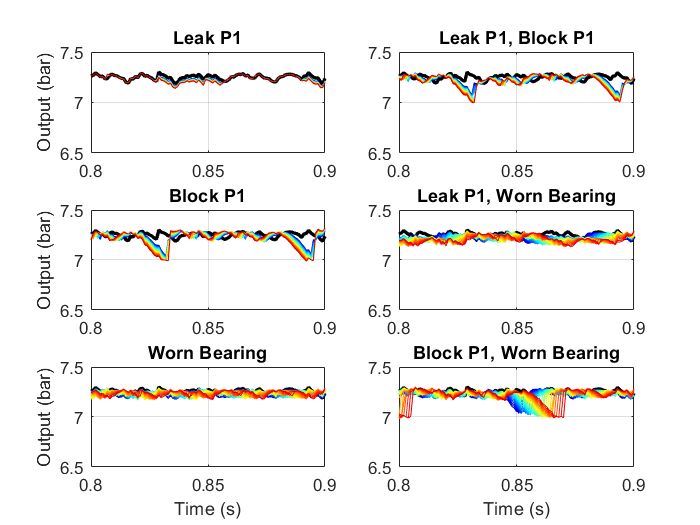

tNom = test_Results(end).meas.time - test_Results(end).meas.time(1);
pNom = test_Results(end).meas.pOut;

plotAllFaultSims(tNom,pNom,tFault,pFault,faultList,numFaults,numSimsPerFault)
subplot(3,2,1),ylabel('Output (bar)'); subplot(3,2,3),ylabel('Output (bar)'); subplot(3,2,5),ylabel('Output (bar)');
subplot(3,2,5),xlabel('Time (s)'); subplot(3,2,6),xlabel('Time (s)');

## Review Fault Progression in the Frequency Domain

Specify number of points for frequency analysis. For deployed applications, the FFT could be streamed or a buffer of Np points could be maintained for computing the frequency response online. We can first compute the FFT for the output pressure under nominal conditions.

Np = 1000;
[freqNom, magNom] = getFFTData(tNom,pNom,Np);

Compute the FFT for all the different fault simulations to observe how the fault signatures progress in the frequency domain.

freqFault = cell(1,numel(tFault));      
magFault  = cell(1,numel(tFault));
for i = 1:numFaults*numSimsPerFault
    [fftFreq, fftMag] = getFFTData(tFault{i},pFault{i},Np);
    freqFault{i} = fftFreq;
    magFault{i} = fftMag;
end

Plot frequency response of all faults and their progressions. Note the unique frequency signatures that each fault (and combinations of faults) exhibit. These unique signatures can be used to diagnose pump faults.

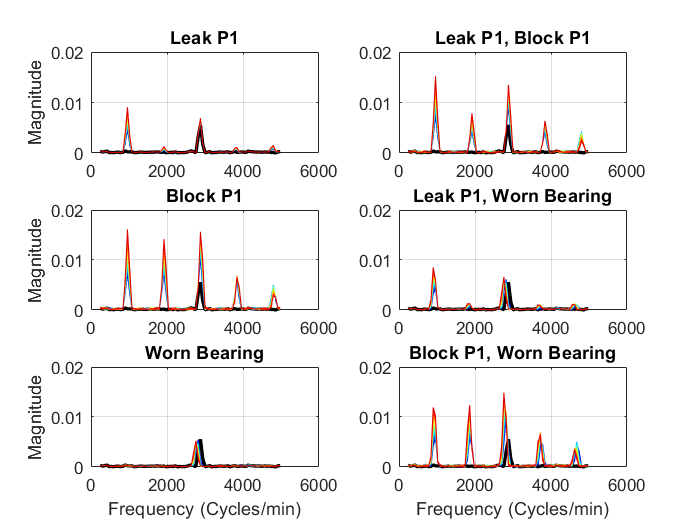

figure;
plotAllFaultSims(freqNom,magNom,freqFault,magFault,faultList,numFaults,numSimsPerFault)
subplot(3,2,1),ylabel('Magnitude'); subplot(3,2,3),ylabel('Magnitude'); subplot(3,2,5),ylabel('Magnitude');
subplot(3,2,5),xlabel('Frequency (Cycles/min)'); subplot(3,2,6),xlabel('Frequency (Cycles/min)');

## Extract Training Data for Fault Detection and Diagnostics Algorithm

Use full simulation results, both nominal and faults, to create table for training machine learning classifier. The "extractPeaks" function uses the findpeaks function to extract out frequency response peaks from the FFT for all triplex simulations.

[freqPks,avgSigs] = extractPeaks(test_Results,numFaults,Np);

To use the extracted frequency response values for machine learning, we can construct a table of all features of interest. We are using the following sensor measurements:

- Pressure Ouput of Triplex Pump (1 kHz sensor) - five frequency peaks and average pressure

- Motor Current (1 kHz sensor) - average current

algo_training_data = array2table([freqPks avgSigs], 'VariableNames', {'Freq_1' 'Peak_1' 'Freq_2' 'Peak_2' 'Freq_3' 'Peak_3' 'Freq_4' 'Peak_4' 'Freq_5' 'Peak_5','PAvg','iAvg'});
algo_training_data.Fault = {test_Results.faults}';
algo_training_data.Fault = categorical(algo_training_data.Fault);
algo_training_data.IntFault = int8(algo_training_data.Fault);
save('sm_pump_triplex_fault_detect_algo_training_data.mat','algo_training_data','-mat');

First five entrees of the table to be used for machine learning.

algo_training_data(1:5,:);

ans = 5×14 table
     Freq_1       Peak_1      Freq_2       Peak_2      Freq_3       Peak_3      Freq_4       Peak_4      Freq_5       Peak_5       PAvg      iAvg      Fault     IntFault
    _________    _________    _______    __________    _______    __________    _______    __________    _______    __________    ______    ______    _______    ________

    0.0020877    0.0061933    0.31524    0.00056271    0.66597     0.0045635    0.67015    0.00081406        NaN           NaN    7.2378     26.46    Leak P1    3    

## Train Machine Learning Classifier

Use the [`classificationLearner`](matlab:classificationLearner) app to train a fault classification model.  Once it's trained, you can export the model or a training function for use.

The Classification Learner can help identify machine learning techniques that work well with our data set. However, often other design factors must be considered as well, such as embedded memory footprint or prediction speed. The documentation page on[ Choosing Classifier Options](matlab: web(fullfile(docroot, 'stats/choose-a-classifier.html#bunt0m5'))) offers additional insights into the classic machine learning techniques.

This code will automatically train a machine learning algorithm using the training data we extracted from the DOE fault tests.

sm_pump_triplex_train_classifiers

## Load Previously Trained Classifier

load('sm_pump_triplex_trained_classifiers.mat');
boostedTreeClass;

boostedTreeClass = struct with fields:
                predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
         RequiredVariables: {'Freq_1'  'Peak_1'  'Freq_2'  'Peak_2'  'Freq_3'  'Peak_3'  'Freq_4'  'Peak_4'  'Freq_5'  'Peak_5'  'PAvg'}
    ClassificationEnsemble: [1×1 classreg.learning.classif.ClassificationEnsemble]
                     About: 'This struct is a trained model exported from Classification Learner R2017b.'
              HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an expo

## Predict Fault with Trained Classifier

The trained machine learning algorithm can be used directly in MATLAB via the "predictFcn". We can check if the trained fault detection and diagnostics algorithm determines the correct type of fault given frequency measurements of the triplex pump output pressure.

faultSim = 16;   % Pick a test
actualFault = table2array(algo_training_data(faultSim,'Fault'));

actualFault = categorical
     Leak P1 


measuredData = algo_training_data(faultSim,1:11);            % Obtain data from that test
faultPrediction = boostedTreeClass.predictFcn(measuredData); % Check fault detection algorithm

faultPrediction = categorical
     Leak P1 


## Export Classifier for use in Desktop Simulation and Embedded Code

The fault detection algorithm can be exported for use in Simulink and be configured for C-code generation for embedded applications. For this particular application, we have configured the output of the classifier to be an int8 type to allow usage of enumerated types.

compactMdl = boostedTreeNumeric.ClassificationEnsemble;

compactMdl =   classreg.learning.classif.CompactClassificationEnsemble
           PredictorNames: {'Freq_1'  'Peak_1'  'Freq_2'  'Peak_2'  'Freq_3'  'Peak_3'  'Freq_4'  'Peak_4'  'Freq_5'  'Peak_5'  'PAvg'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3 4 5 6 7]
           ScoreTransform: 'none'
               NumTrained: 30


  Properties, Methods


saveCompactModel(compactMdl,'sm_pump_triplex_fault_detect_algo');

## Helper functions for this live script

This section has multiple functions that are used throughout this live script.

The "sortFaultTests" function takes in simulation results from the triplex model and removes the nominal simulations. Removing nominal simulations is useful for analyzing and comparing fault progressions.

function [sortedFaults,tFault,yFault,faultList] = sortFaultTests(allSimResults)
    remNomIdx = ~strcmp({allSimResults.faults},'Nominal');
    sortedFaults = allSimResults(remNomIdx);
    [~,sortedTests] = sort({sortedFaults.faults});
    sortedFaults = sortedFaults(sortedTests);
    tFault = cell(1,numel(sortedFaults));
    yFault = cell(1,numel(sortedFaults));
    for i = 1:numel(sortedFaults)
        tFault{i} = sortedFaults(i).meas.time - sortedFaults(i).meas.time(1);
        yFault{i} = sortedFaults(i).meas.pOut;
    end
    faultList = {sortedFaults.faults};
end

The "plotAllFaultSims" function takes a single nominal simulation and then plots the progression of all the faults simulated by the triplex pump.

function plotAllFaultSims(xNom,yNom,xFault,yFault,faultList,numFaults,numSimsPerFault)
    plot_order = [3 6 1 2 4 5];
    color_order = jet(numSimsPerFault);
    simlog_handles = repelem(axes,numFaults);
    for i = 1:numFaults
        simlog_handles(i) = subplot(3,2,plot_order(i));
        plot(xNom,yNom,'k', 'LineWidth', 2);
        grid on; box on; hold on; plotNum = 1;
        if xNom(1) < 0.1
            xlim([0.8 0.9])
        end
        for j = (i-1)*numSimsPerFault+1:i*numSimsPerFault
            plot(xFault{j},yFault{j},'Color',color_order(plotNum,:));
            plotNum = plotNum + 1;
        end
        title(faultList{(i-1)*numSimsPerFault+1});
    end
    hold off;
    linkaxes(simlog_handles, 'xy');
end

The "getFFTData" function computes the FFT of the input signal given the number of points specified, Np.

function [freq, mag] = getFFTData(tout,yout,np)
    % Find sample rate of input data
    dt = tout(2) - tout(1);
    
    % Use last Np points for FFT
    yout_intp = yout(end-np+1:end); 
    
    % % Compute fft
    yout_intp = yout_intp(:).*hamming(np);
    f = fft(yout_intp)/np;
    f2 = f(1:(np/2)+1);
    w = (0:np/2)/np*(2*pi/dt);
    P = abs(f2);
    ind = 20 < w & w < 525; % Between 20 & 525 radians/sec
    freq = w(ind)'*60/(2*pi);
    mag = P(ind);
end

The "extractPeaks" function is used to compute the FFT of the nominal and fault simulation runs and to determine frequency peaks and other features of interest for training a machine learning algorithm.

function [freqPks,avgSigs] = extractPeaks(test_Results,numFaults,Np)
   
    numFaultSims = length(find(strcmp({test_Results.faults},'Leak P1')));
    numNomSims = (length(find(strcmp({test_Results.faults},'Nominal'))) - 1)/numFaults;
    numSimsPerFault = numFaultSims + numNomSims;
    
    currentSpeed = 958;
    numPeaks = 5;
    freqPks = NaN(numFaults*numSimsPerFault + 1,2*numPeaks);
    avgSigs = NaN(numFaults*numSimsPerFault + 1,2);
    
    arrayIdx = 1;
    for i = 1:numFaults+1
        
        if i <= numFaults
            faultIdx = (i-1)*numSimsPerFault+1:i*numSimsPerFault;
        else
            faultIdx = (i-1)*numSimsPerFault+1:(i-1)*numSimsPerFault + 1;
        end
            
        for j = faultIdx
            [freqFault, magFault] = getFFTData(test_Results(j).meas.time - ...
                test_Results(j).meas.time(1),test_Results(j).meas.pOut,Np);
            
            freqFaultSpd = freqFault/(currentSpeed*3);
            [pks,loc] = findpeaks(magFault,'MinPeakProminence',0.5e-3);
            
            % Center around primary speed
            normSpd = abs(freqFaultSpd(loc)-1);
            [sortFreq,sortIdx] = sort(normSpd);
            sortMag = pks(sortIdx);
                   
            if length(sortMag) <= numPeaks
                numFreq = length(sortMag);
            else
                numFreq = numPeaks;
            end
                    
            avgSigs(arrayIdx,1) = mean(test_Results(j).meas.pOut(1:Np));
            avgSigs(arrayIdx,2) = mean(test_Results(j).meas.iMotor(1:Np));
            freqPks(arrayIdx,1:2:numFreq*2) = sortFreq(1:numFreq);
            freqPks(arrayIdx,2:2:numFreq*2) = sortMag(1:numFreq);
            
            arrayIdx = arrayIdx + 1;
        end
    end
end